# `datetime` Variables

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

manU = readtable("./data/data.xlsx", Sheet="manU")

manU = 38×4 table
          GameTime          Place         Opponent          Points
    ____________________    _____    ___________________    ______

    17-May-2016 20:00:00    {'H'}    {'AFC Bournemouth'}      3   
    12-Dec-2015 17:30:00    {'A'}    {'AFC Bournemouth'}      0   
    28-Feb-2016 14:05:00    {'H'}    {'Arsenal FC'     }      3   
    04-Oct-2015 16:00:00    {'A'}    {'Arsenal FC'     }      0   
    16-Apr-2016 15:00:00    {'H'}    {'Aston Villa'    }      3   
    14-Aug-2015 19:45:00    {'A'}    {'Aston Villa'    }      3   
    28-Dec-2015 17:30:00    {'H'}    {'Chelsea FC'     }      1   
    07-Feb-2016 16:00:00    {'A'}    {'Chelsea FC'     }      1   
    20-Apr-2016 20:00:00    {'H'}    {'Crystal Palace' }      3   
    31-Oct-2015 15:00:00    {'A'}    {'Crystal Palace' }      1   
    03-Apr-2016 16:00:00    {'H'}    {'Ev

manU(1:4, :)

ans = 4×4 table
          GameTime          Place         Opponent          Points
    ____________________    _____    ___________________    ______

    17-May-2016 20:00:00    {'H'}    {'AFC Bournemouth'}      3   
    12-Dec-2015 17:30:00    {'A'}    {'AFC Bournemouth'}      0   
    28-Feb-2016 14:05:00    {'H'}    {'Arsenal FC'     }      3   
    04-Oct-2015 16:00:00    {'A'}    {'Arsenal FC'     }      0   


manU.GameTime(1:4)

ans = 4×1 datetime array
   17-May-2016 20:00:00
   12-Dec-2015 17:30:00
   28-Feb-2016 14:05:00
   04-Oct-2015 16:00:00


## Task 1

The `manU` variable contains a list of Manchester United games in the 2015-2016 season. Notice that the `GameTime` variable is a `datetime` array. You can perform many functions directly on `datetime` arrays.

manU = sortrows(manU, "GameTime")

manU = 38×4 table
          GameTime          Place            Opponent            Points
    ____________________    _____    ________________________    ______

    08-Aug-2015 12:45:00    {'H'}    {'Tottenham Hotspur'   }      3   
    14-Aug-2015 19:45:00    {'A'}    {'Aston Villa'         }      3   
    22-Aug-2015 12:45:00    {'H'}    {'Newcastle United'    }      1   
    30-Aug-2015 16:00:00    {'A'}    {'Swansea City'        }      0   
    12-Sep-2015 17:30:00    {'H'}    {'Liverpool FC'        }      3   
    20-Sep-2015 16:00:00    {'A'}    {'Southampton FC'      }      3   
    26-Sep-2015 15:00:00    {'H'}    {'Sunderland AFC'      }      3   
    04-Oct-2015 16:00:00    {'A'}    {'Arsenal FC'          }      0   
    17-Oct-2015 15:00:00    {'A'}    {'Everton FC'          }      3   
    25-Oct-2015 14:05:00    {'H'}    {'Manchester Cit

## Task 2

ptsTot = cumsum(manU.Points)

ptsTot =      3
     6
     7
     7
    10
    13
    16
    16
    19
    20


## Task 3

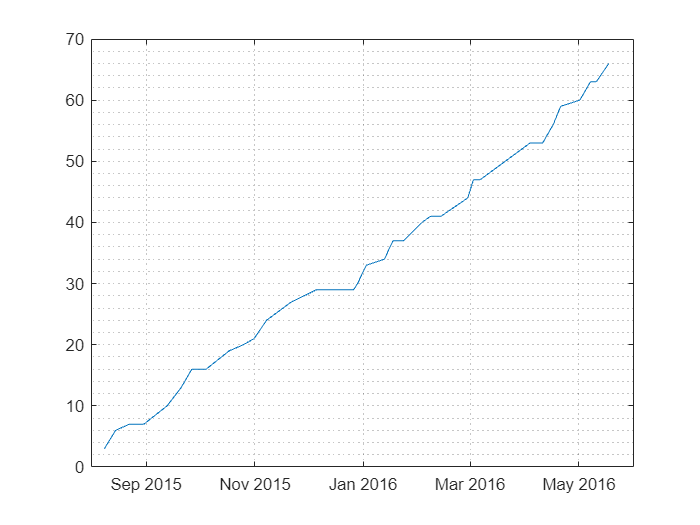

plot(manU.GameTime, ptsTot)
grid minor